# Step 11: 設定

GUILDA の解析は、オプションを省略すると「設定」の値を既定値として使います。設定は `GUILDA.setting` で変え、`GUILDA.config` で読み出します。この Step では、設定の分類と読み出し方、各解析の既定値、呼び出しごとの上書きとの関係、設定の変え方と戻し方、起動時の設定を順に扱います。

設定は、GUILDA の基本的な流れの赤枠の解析（潮流計算、時間シミュレーション、近似線形化、連続潮流計算、最適潮流計算）の既定値を決めます。

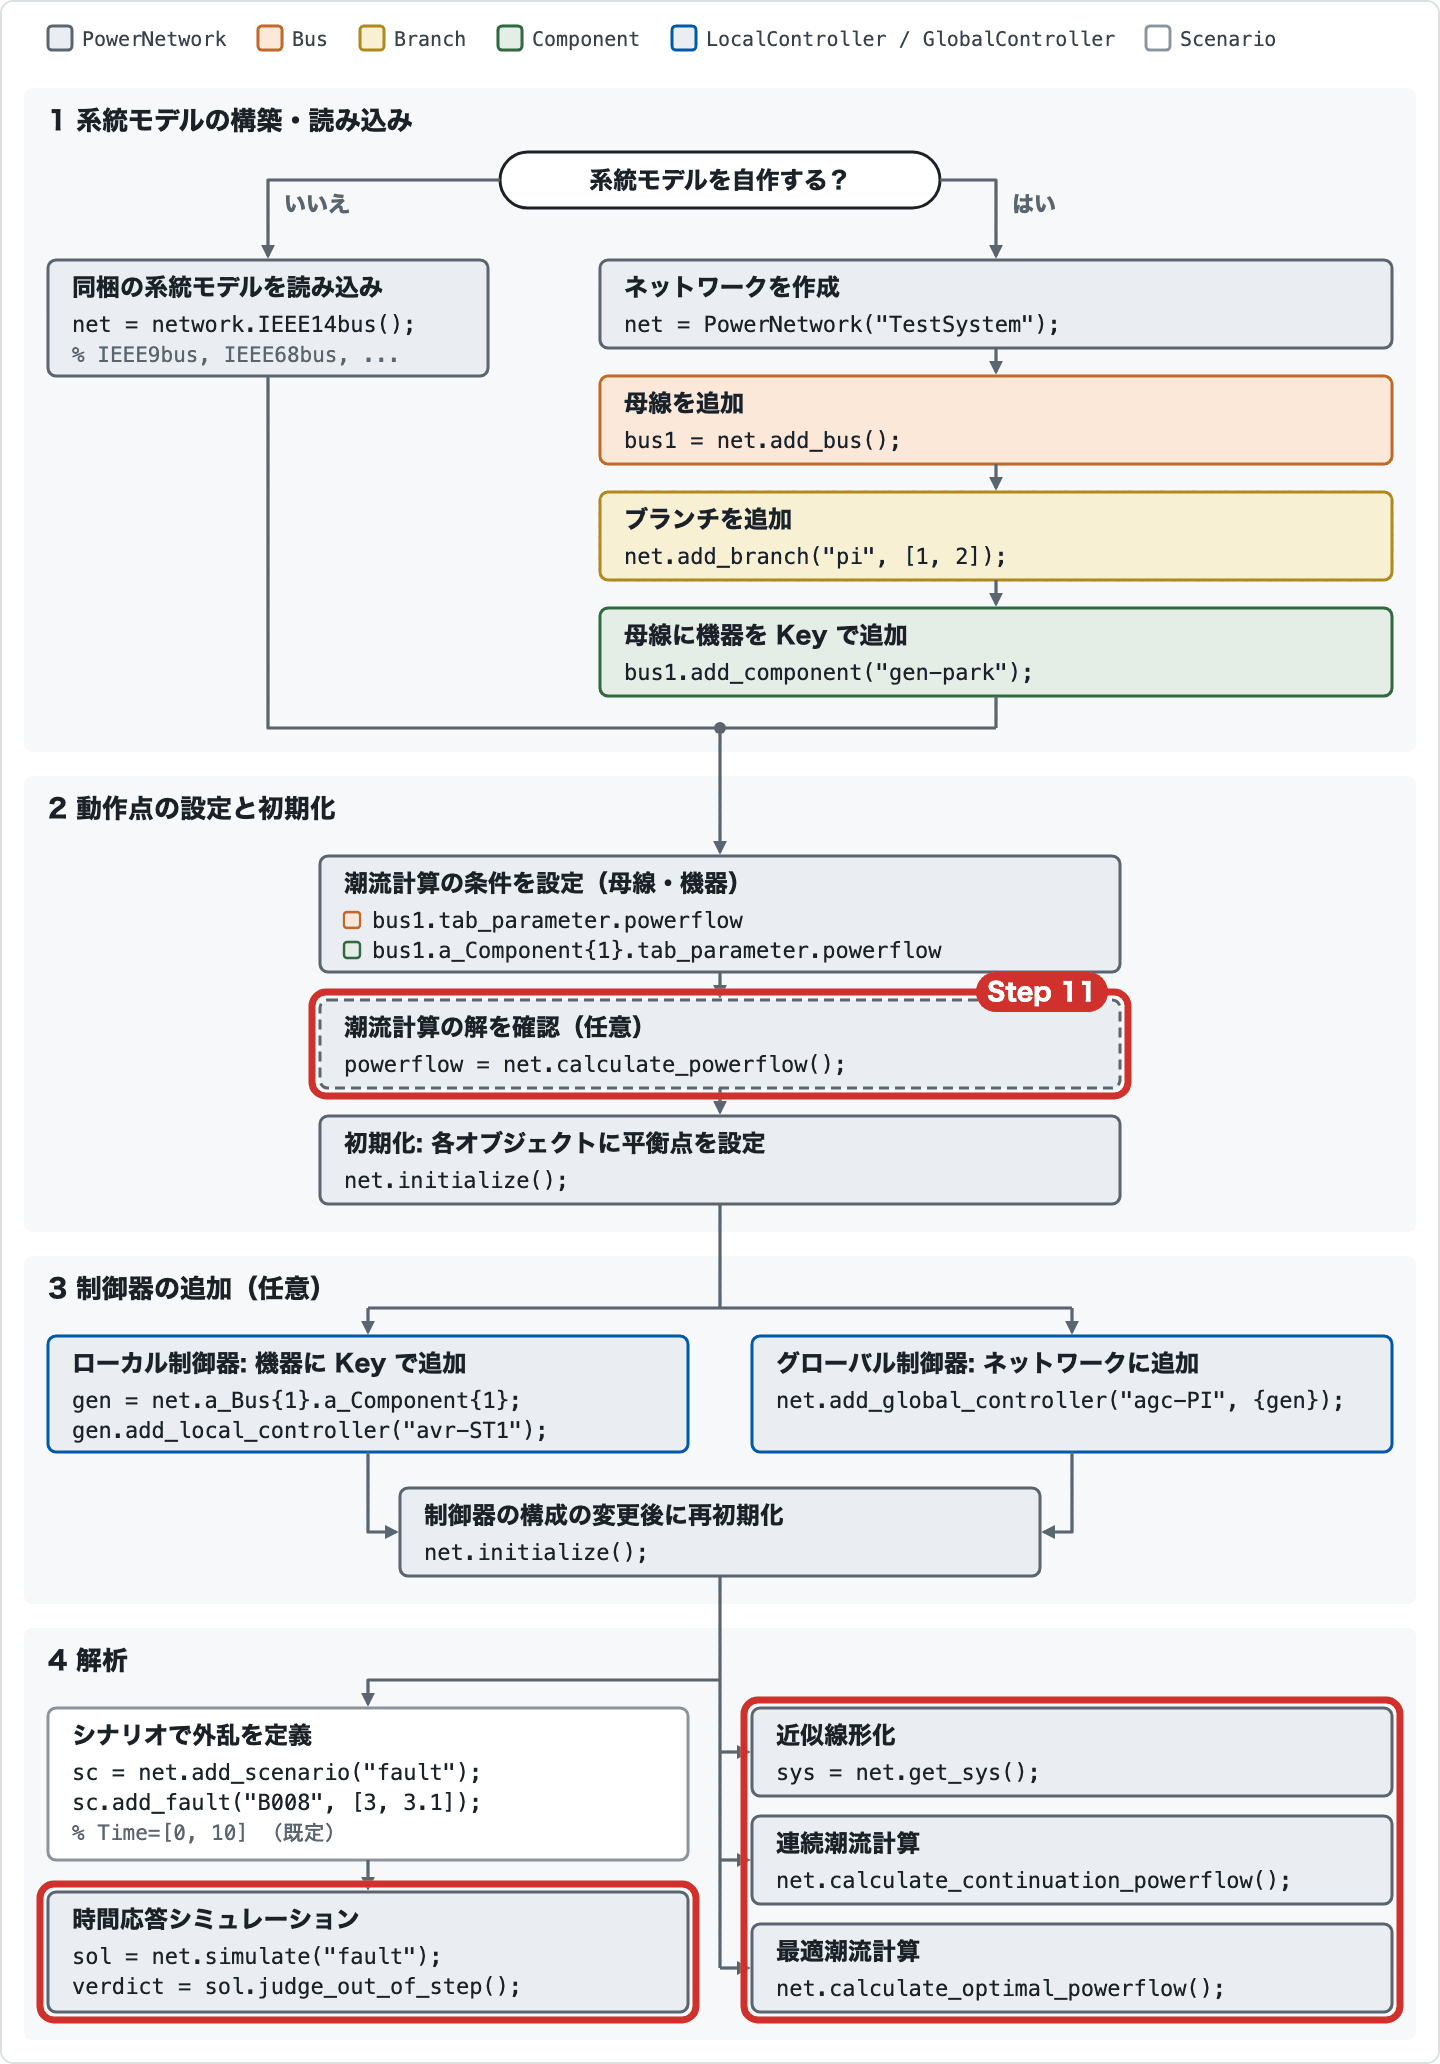

**この Step で分かること**

- 設定の分類（カテゴリ）と、設定画面の開き方

- `GUILDA.config` による設定の読み出し

- 潮流計算・時間シミュレーション・最適潮流計算・連続潮流計算・近似線形化の既定値

- Name-Value オプションによる呼び出しごとの上書きと、設定との関係

- コマンド `GUILDA.setting("カテゴリ", 名前=値)` で設定を変える方法と、既定値に戻す方法

- 起動時の設定（`Startup`）とメッセージの設定（`Message`）

各節は、設定を読み書きするのに要るコードだけで進みます。**確かめる（省略できます）** の下のコードは、中身を見るためのものです。飛ばしても最後まで動きます。

**注意:** 設定を変えると、利用者の設定ファイル（`@GUILDA/user` フォルダ）が書き換わり、MATLAB を再起動しても残ります。このライブスクリプトは、変えた設定を最後に必ず元の値へ戻します。途中で止めたときは、最後の節「10. 設定を元に戻す」を実行してください。

## 1. 設定の分類と設定画面

設定はカテゴリに分かれています。

設定は画面でも変えられます。次のコマンドを実行すると、設定画面が開きます（このライブスクリプトでは実行しません。コマンドウィンドウに入力してください）。

- `GUILDA.setting`: 設定画面。左にカテゴリの一覧、右に選んだカテゴリの設定が、名前・入力欄・説明の順に並びます。値を変えて **Apply** を押すと保存され、**Close** で閉じます（未保存の変更があると確認します）。

**注意:** 入力欄は種類に応じて、チェックボックス（`logical`）、ドロップダウン（`select`）、テキスト欄（`double`、`string`）になります。不正な値を入れると、警告が出て元の値に戻ります。数値の配列は `[0.1 0.02]` のように、文字列の並びは `Q, V` のようにカンマで区切って入力します。

**確かめる（省略できます）**

`GUILDA.config()` は全カテゴリを構造体で返すので、フィールド名がカテゴリの一覧です。

string(fieldnames(GUILDA.config()))

ans = 8×1 の string 配列
    "Startup"
    "Message"
    "PowerSystemModel"
    "PowerFlowCalculation"
    "OptimalPowerFlow"
    "ContinuationPowerFlow"
    "TimeSimulation"
    "ApproximateLinearization"


## 2. 設定を読み出す

`GUILDA.config(カテゴリ, 名前)` で 1 つの設定の値を読み出します。

tol_pf = GUILDA.config("PowerFlowCalculation", "Tolerance")

tol_pf = 1.0000e-08

**注意:** `GUILDA.config` は設定ファイルを最初の 1 回だけ読み、以後は記憶した値を返します。`GUILDA.setting` で変えたときは自動で読み直します。設定ファイルを直接編集したときの読み直し方は、6 節の注意で扱います。使い方の詳細は `help GUILDA.config` で確かめられます。

**確かめる（省略できます）**

名前を省略すると、そのカテゴリの全設定を構造体で返します。各設定には、値 `Value`、種類 `Type`、説明 `Description` があり、条件 `Valid` や選択肢 `options` を持つものもあります。

sct_pf = GUILDA.config("PowerFlowCalculation");
sct_pf.Tolerance

ans = フィールドをもつ struct:
          Value: 1.0000e-08
           Type: "double"
          Valid: "v > 0"
    Description: "[pu] Largest P/Q mismatch of a converged solution (every method)"


sct_pf.Solver

ans = フィールドをもつ struct:
          Value: "newton"
           Type: "select"
        options: ["newton"    "gradient"    "levenberg-marquardt"    "fsolve"    "dynamic"]
    Description: "Algorithm: 'newton', 'gradient', 'levenberg-marquardt', 'fsolve' (needs Optimization Toolbox) or 'dynamic' (virtual bus dynamics)"


## 3. 各解析の既定値

`GUILDA.config(カテゴリ, Format="table")` は、カテゴリの全設定を 1 行 1 設定の表（名前、種類、値、説明）で返します。各解析の既定値を、この表で確かめます。

**注意:** 多くの解析に共通の設定として、`Verbose`（途中経過の表示）、`Progress`（進捗の表示: `"dialog"`、`"disp"`、`"none"`）、`PlotFcn`（解析中のライブ表示）があります。

**確かめる（省略できます）**

各カテゴリの表です。

GUILDA.config("PowerFlowCalculation", Format="table")

ans = 12×4 table
                 Name                   Type           Value                                                                                            Description                                                                                    
    ______________________________    _________    ______________    __________________________________________________________________________________________________________________________________________________________________________________

    "Solver"                          "select"     {["newton"  ]}    "Algorithm: 'newton', 'gradient', 'levenberg-marquardt', 'fsolve' (needs Optimization Toolbox) or 'dynamic' (virtual bus dynamics)"                                               
    "Tolerance"                       "double"     {[1.0000e-08]}    "[pu] Largest P/Q mismatch of a converged solution (every method)"                                                                                                       

GUILDA.config("TimeSimulation", Format="table")

ans = 13×4 table
             Name               Type           Value                                                                                                            Description                                                                                                   
    ______________________    _________    ______________    _________________________________________________________________________________________________________________________________________________________________________________________________________________

    "Solver"                  "select"     {["ode15s"  ]}    "Solver of the MATLAB ode object (a solver for DAEs)"                                                                                                                                                            
    "Tolerance"               "double"     {[1.0000e-04]}    "Relative error tolerance, 'RelativeTolerance' of the ode object (1e-15 <= tol <= 1e-3)"                    

GUILDA.config("OptimalPowerFlow", Format="table")

ans = 21×4 table
                 Name                    Type                  Value                                                                                                          Description                                                                                            
    _______________________________    _________    ___________________________    __________________________________________________________________________________________________________________________________________________________________________________________________

    "Method"                           "select"     {["AC OPF"               ]}    "Formulation: 'ELD' (economic load dispatch, branches ignored), 'DC OPF' (DC approximation) or 'AC OPF' (AC power flow equations)"                                                                
    "Solver"                           "select"     {["auto"                 ]}    "Optimization solver ('auto': the solver that 'solve' chooses for

GUILDA.config("ContinuationPowerFlow", Format="table")

ans = 13×4 table
             Name                Type           Value                                                                                                         Description                                                                                                 
    _______________________    _________    ______________    ____________________________________________________________________________________________________________________________________________________________________________________________________________

    "InitialLambda"            "double"     {[         0]}    "lambda at the starting point (the equilibrium)"                                                                                                                                                            
    "MaxIteration"             "double"     {[       500]}    "Maximum number of predictor-corrector steps"                                                                          

GUILDA.config("ApproximateLinearization", Format="table")

ans = 3×4 table
      Name         Type        Value                                                                                    Description                                                                              
    _________    ________    __________    ______________________________________________________________________________________________________________________________________________________________________

    "Type"       "select"    {["ODE" ]}    "Model of net.get_sys and result.get_ss(): 'ODE' (the bus voltages eliminated) or 'DAE' (the connected model with the bus voltages as algebraic variables)"           
    "Port"       "select"    {["PQ"  ]}    "Bus port of the 'DAE' model (bus variables v, current balance w): 'PI': v=[theta, V], w=[P, Q/V]; 'PQ': v=[theta, log V], w=[P, Q]; 'I': v=[Vre, Vim], w=[-Iim, Ire]"
    "PlotFcn"    "select"    {["none"]}    "Live display during the analysis ('none'; other displays are under development). The figure after t

## 4. 呼び出しごとに上書きする

解析の Name-Value オプションに値を渡すと、その呼び出しにだけ効きます。設定は変わりません。潮流計算で、収束判定 `Tolerance` を 1e-12 にして計算します。

net = network.IEEE9bus();
result_tight = net.calculate_powerflow(Tolerance=1e-12);

**注意:** 優先順位は「呼び出しのオプション」→「設定」です。ほかに、系統ごとに覚えておく解析の条件が `net.solver_PF`、`net.solver_CPF` などのソルバーにあります（例: 連続潮流計算の `LoadBus`）。これは設定ではなく系統の持ち物で、`net.reset_solver` で初期状態に戻ります。

**確かめる（省略できます）**

結果の `options` には、その計算で実際に使った値が残ります。オプションを省略した計算と比べると、設定の `Tolerance` は元の値のままです。

result_default = net.calculate_powerflow();
tol_default_call = result_default.options.Tolerance

tol_default_call = 1.0000e-08

tol_this_call    = result_tight.options.Tolerance

tol_this_call = 1.0000e-12

tol_setting      = GUILDA.config("PowerFlowCalculation", "Tolerance")

tol_setting = 1.0000e-08

## 5. コマンドで設定を変える

`GUILDA.setting("カテゴリ", 名前=値)` で設定を変えると、`@GUILDA/user` に保存され、次の呼び出しからの既定値になります。ここでは、元の値を変数に取っておいてから、`Tolerance` を 1e-10 に変えます。

tol_original = GUILDA.config("PowerFlowCalculation", "Tolerance");
GUILDA.setting("PowerFlowCalculation", Tolerance=1e-10)

1 回の呼び出しで、同じカテゴリの複数の設定を変えることもできます。`Tolerance` を 1e-9 に、途中経過の表示 `Verbose` を `true` にします。

verbose_original = GUILDA.config("PowerFlowCalculation", "Verbose");
GUILDA.setting("PowerFlowCalculation", Tolerance=1e-9, Verbose=true)

値は種類と条件で検査されます。不正な値や、無い名前・カテゴリはエラーになり、何も変わりません。`select` の設定には選択肢 `options` にある文字列だけを、`logical` の設定には `true` か `false` を渡します。使い方の詳細は `help GUILDA.setting` で確かめられます。

**確かめる（省略できます）**

変えた値が設定に入り、オプションを省略した呼び出しで使われることを確かめます。

GUILDA.config("PowerFlowCalculation", "Tolerance")

ans = 1.0000e-09

GUILDA.config("PowerFlowCalculation", "Verbose")

ans = logical
   1


result_new = net.calculate_powerflow();

  newton  iter    0   max mismatch 6.162e-15
✔ The Newton-Raphson iteration has converged within the tolerance limit (0 iterations).


result_new.options.Tolerance

ans = 1.0000e-09

不正な値（負の `Tolerance`）と、無い名前（`Tol`）を渡すとエラーになり、設定は変わりません。

try
    GUILDA.setting("PowerFlowCalculation", Tolerance=-1)
catch ME
    disp(ME.message)
end

invalid value for setting Tolerance of PowerFlowCalculation: expected a real numeric scalar with v > 0; no setting was changed


try
    GUILDA.setting("PowerFlowCalculation", Tol=1e-10)
catch ME
    disp(ME.message)
end

unknown setting "Tol" in category PowerFlowCalculation; the settings are Solver, Tolerance, MaxIteration, NewtonStepSize, GradientStepSize, FsolveUseParallel, FsolveMaxFunctionEvaluations, WhenFailed, Verbose, Progress, WarmStart, PlotFcn


GUILDA.config("PowerFlowCalculation", "Tolerance")

ans = 1.0000e-09

## 6. 既定値に戻す

GUILDA に付属の既定値は `@GUILDA/config` フォルダの `Default<カテゴリ>.json` にあります。これを読んで、設定に渡し直すと既定値に戻ります。

sct_default = readstruct(fullfile(GUILDA.pwd, "@GUILDA", "config", "DefaultPowerFlowCalculation.json"));
GUILDA.setting("PowerFlowCalculation", Tolerance=sct_default.Tolerance.Value)

**注意:** カテゴリの設定をまとめて既定値に戻すには、`@GUILDA/user` にある同じ名前のファイル（例: `DefaultPowerFlowCalculation.json`）を削除してから `GUILDA.config([], [], reset=true)` を実行します。GUILDA の新しい版で既定値のファイルが変わったカテゴリは、起動時に自動で既定値に戻ります（INFO で知らせます）。手で書き換えて条件に合わなくなった値も、読み込むときに既定値に戻ります。

**確かめる（省略できます）**

sct_default.Tolerance.Value

ans = 1.0000e-08

GUILDA.config("PowerFlowCalculation", "Tolerance")

ans = 1.0000e-08

## 7. 起動時の設定（Startup）

`GUILDA` を実行したときの処理は `Startup` カテゴリで決まります。

たとえば起動時にチュートリアルを開かないようにするには `GUILDA.setting("Startup", Tutorial=false)` とします（このライブスクリプトでは実行しません）。次に `GUILDA` を実行したときから効きます。

`DeveloperPath` は、パスを加える `GUILDA.addpath` が読みます。`GUILDA` の起動時に `GUILDA.addpath` が実行されるので、変えた後は `GUILDA.addpath` を実行するか、次の起動から効きます。`false` に戻すと、次の `GUILDA.addpath` でフォルダがパスから外れます。

**注意:** パスの追加そのものは省略できません。`DeveloperPath` は、ドキュメントの図を描くスクリプトなど、GUILDA の開発者向けのファイルを使うときだけ `true` にします。

**確かめる（省略できます）**

GUILDA.config("Startup", Format="table")

ans = 6×4 table
           Name             Type         Value                                                                                                     Description                                                                                              
    __________________    _________    __________    _______________________________________________________________________________________________________________________________________________________________________________________________________

    "PrintLogo"           "logical"    {[     1]}    "Print the GUILDA logo at startup"                                                                                                                                                                     
    "CheckRequirement"    "logical"    {[     1]}    "Verifying version requirements at startup"                                                                                                                                

## 8. メッセージと系統モデルの設定

`Message` カテゴリは GUILDA の警告（`ShowWarning`）と INFO メッセージ（`ShowInfo`）を表示するかを決めます。`PowerSystemModel` カテゴリの `Hz` は、新しく作る系統の定格周波数の既定値です。

**注意:** `ShowWarning=false` にすると GUILDA の警告がすべて出なくなり、問題に気づきにくくなります。授業や大量の計算で表示を減らしたいときに、一時的に使います。

**確かめる（省略できます）**

GUILDA.config("Message", Format="table")

ans = 2×4 table
        Name           Type       Value               Description            
    _____________    _________    _____    __________________________________

    "ShowWarning"    "logical"    {[1]}    "Show the warnings of GUILDA"     
    "ShowInfo"       "logical"    {[1]}    "Show the INFO messages of GUILDA"


GUILDA.config("PowerSystemModel", Format="table")

ans = 1×4 table
    Name      Type      Value       Description   
    ____    ________    ______    ________________

    "Hz"    "double"    {[60]}    "Grid Frequency"


## 9. 設定ファイルの保存先と、解析ごとの設定

`GUILDA.setting` や設定画面で保存した値は、`@GUILDA/user` フォルダのカテゴリごとの JSON ファイル（例: `@GUILDA/user/DefaultPowerFlowCalculation.json`）に入ります。

**注意:** `@GUILDA/user` と `@GUILDA/config` のファイルは GUILDA が読み書きします。直接編集せず、`GUILDA.setting` を使ってください。

解析のカテゴリと、その解析を扱う Step の対応です。

## 10. 設定を元に戻す

この Step で変えた設定を、5 節の最初に取っておいた値に戻します。

GUILDA.setting("PowerFlowCalculation", Tolerance=tol_original, Verbose=verbose_original)

**確かめる（省略できます）**

GUILDA.config("PowerFlowCalculation", "Tolerance")

ans = 1.0000e-08

GUILDA.config("PowerFlowCalculation", "Verbose")

ans = logical
   0


## まとめ

- 設定はカテゴリに分かれ、設定画面（`GUILDA.setting`）かコマンド `GUILDA.setting("カテゴリ", 名前=値)` で変え、`GUILDA.config` で読み出します。

- 解析のオプションを省略すると設定の値が使われます。呼び出しで渡した値はその呼び出しにだけ効き、`result.options` に残ります。

- 変えた設定は `@GUILDA/user` に保存され、MATLAB を再起動しても残ります。既定値は `@GUILDA/config` のファイルにあります。

- 起動時の処理（ロゴ、要件の確認、キーの更新、チュートリアル、開発者用パス）は `Startup` で選べます。

## 次の Step と関係する Part

- 次の Step 12（データの入出力）では、系統モデルとシナリオのファイルへの保存・読み込みと、結果の書き出しを扱います。

- 各解析の設定の意味は、解析とあわせて講義ノートで説明しています: [講義ノート Part 2](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part2-power-flow.html","-browser"))・[講義ノート Part 3](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part3-time-simulation.html","-browser"))・[講義ノート Part 5](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part5-linearization.html","-browser"))・[講義ノート Part 6](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part6-optimal-power-flow.html","-browser"))・[講義ノート Part 7](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part7-continuation-power-flow.html","-browser"))（ブラウザで開きます）

[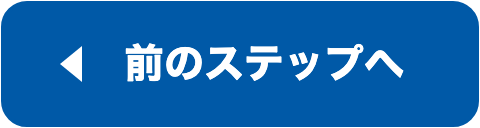](matlab:open('Step10_ContinuationPowerFlow.mlx'))　　[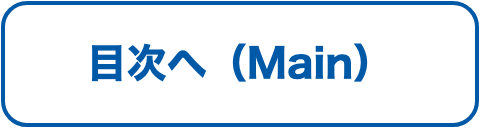](matlab:open('Main.mlx'))　　[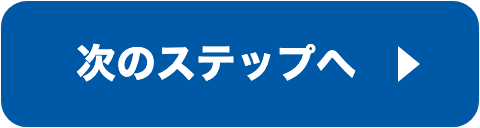](matlab:open('Step12_DataIO.mlx'))